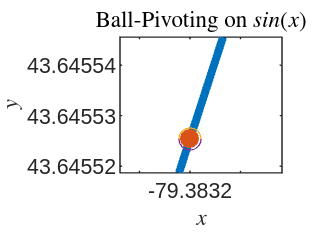

guess = -79.3832

guess = NaN

Error using fzero
Second argument must be finite.

clear
load("../propagator_ver2/beta.mat")
f = @(x) beta(1) + x * beta(2) + x.^2 * beta(3) ;
df = @(x) beta(2) + 2*x*beta(3)
r = 87.5/(40076e3);
x0 = -79.3832;
n = 3;
warning('off')
x = linspace(x0 - r, x0 + n*r, 100);
plot(x, f(x), linewidth = 3)
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")

title("Ball-Pivoting on $sin(x)$", "Interpreter","latex")
axis equal
opts = optimset('display', 'none');
coord = zeros(1, n);
hold on
for i = 1:n
    y0 = f(x0);
    scatter(x0, y0, 50, "filled")
    
    circ_top = @(x, x0, y0) y0 + sqrt(r.^2 - (x - x0).^2);
    circ_bot = @(x, x0, y0) y0 - sqrt(r.^2 - (x - x0).^2);

    f2_1 = @(x) circ_top(x, x0, y0);
    f2_2 = @(x) circ_bot(x, x0, y0);
    f_zer1 = @(x) f(x) - f2_1(x);
    f_zer2 = @(x) f(x) - f2_2(x);
    
    x_new = linspace(x0 - r, x0 + r, 100);
    plot(x_new, f2_1(x_new), x_new, f2_2(x_new));
    
    guess = x0 + r/2
    
    xx = fzero(f_zer1, guess, opts);
    if isnan(xx)
        guess = guess - r/10;
        xx = fzero(f_zer1, guess, opts);
        if guess == x0
            break;
        end
    end
    guess = x0 + 9*r/10;
    if isnan(xx)
        guess = guess - r/10;
        xx = fzero(f_zer2, guess, opts);
        if guess == x0
            break;
        end
    end
    coord(1, i) = xx;
    x0 = xx;
    scatter(coord(1, i), f(coord(1, i)), 50, "filled")
end

saveas(gcf, "demo.pdf")
hold off